# Transfer Functions in MATLAB

## Defining Transfer Functions

We wish to define and then study the behavior of the transfer function


$$G\left(s\right)=\frac{1}{1+\textrm{RC}\;s}\ldotp$$


We start by providing numerical values for the coefficients `R` and `C` and defining `s` as a *"tf" *MATLAB object.

*[Note:] You'll need to install the ****Control Systems Toolbox**** add-on (or similar) to get access to the functions used in this LiveScript.*

% Housekeeping
clc; clear; close all

% Coefficients
R = 10;
C = 2;

% Define s as the Laplace operator
s = tf('s');

This allows us to define the transfer function $G\left(s\right)$ by simply writing down its equation.

% Define transfer function
G  = 1/(1+R*C*s)

G =
 
     1
  --------
  20 s + 1
 
Continuous-time transfer function.



Alternatively, we can define $G\left(s\right)$ based on the coefficients of the numerator and denominator, interpreted as polynomial functions of `s`

$G\left(s\right)=\frac{1\cdot s^0 }{20\cdot s^1 +1\cdot s^0 }$.

Numerator coefficient "vector": $\left\lbrack 1\right\rbrack$

Denominator coefficient vector: $\left\lbrack 20\;\;1\right\rbrack$

% Alternative definition using the polynomial coefficients
G2 = tf(1,[20 1])

G2 =
 
     1
  --------
  20 s + 1
 
Continuous-time transfer function.



## Built-in Plotting Tools

Given our transfer function, we can now plot its impulse response (input is the Dirac pulse $\delta \left(t\right)$) and its step response (input is the Heviside function $u\left(t\right)$). We do so by using the built-in MATLAB functions `inpulse` and `step`, which automatically output a figure.

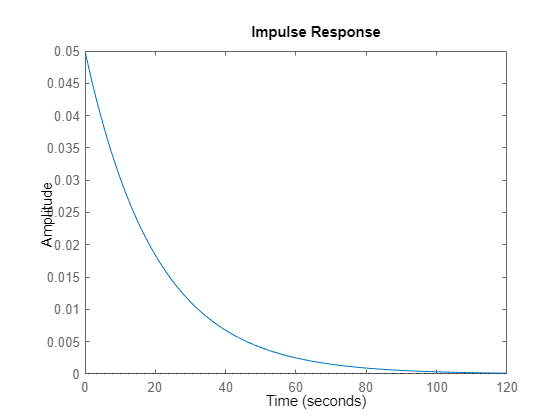

impulse(G)

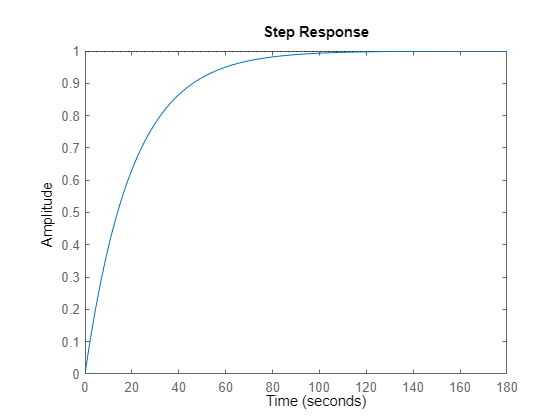

step(G)

pause(0.1) % Hack: forces MATLAB to draw the plot here

*[Note:] Figures generated using built-in functions don't always behave like normal plots, especially when used in LiveScripts. This is why I had to add the *`pause`* and *`figure`* commands to get things to work properly in this code. To avoid these bugs, it is often preferable to have your built-in functions output the raw data and then use "traditional" plotting tools. *

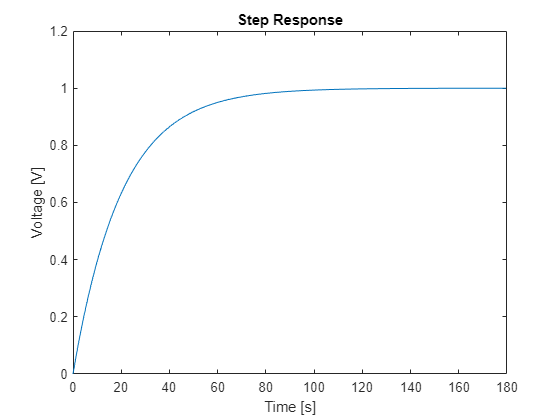

figure % Hack: Reinitializes the figure settings

% Output raw data
[y,t] = step(G);

% Plot normally
plot(t,y);
title('Step Response')
xlabel('Time [s]')
ylabel('Voltage [V]')
ylim([0 1.2])

## Studying the effects of a parameter

We now wish to make an animation to study the behavour of $G\left(s\right)$ for different values of $R$.

To do so, we will write a `for` loop that cycles through different values of `R`, defines the transfer function, computes the step response, and plots it. When used inside a `for` loop, the `pause` command causes the LiveScript to generate an animation.

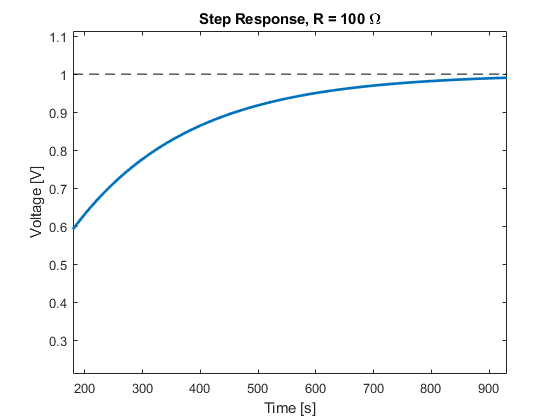

for Rval = 5:5:100
    % Define Transfer Function
    Gr  = 1/(1+Rval*C*s);
    
    % Compute step response up until T=1000
    [y,t] = step(Gr,1000);
    
    % Plot the step response
    plot(t,y,'LineWidth',2)
    hold on
    plot([0 1000],[1 1],'--k')
    title(['Step Response, R = ' num2str(Rval) ' \Omega'])
    xlabel('Time [s]')
    ylabel('Voltage [V]')
    ylim([0 1.2])
    hold off
    pause(0.1)
end

## Response to an Arbitrary Input

If we wish to study how the system responds to an arbitrary input, we can use the function `lsim`. 

#### Response to a Pulse

To study how the system reacts to the pulse


$$p\left(t\right)=\left\lbrace \begin{array}{ll}
5 & \textrm{if}\;t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & \textrm{otherwise}
\end{array}\right.$$


we begin by defining our input in terms of a time vector `tp` and the corresponding values of `p`

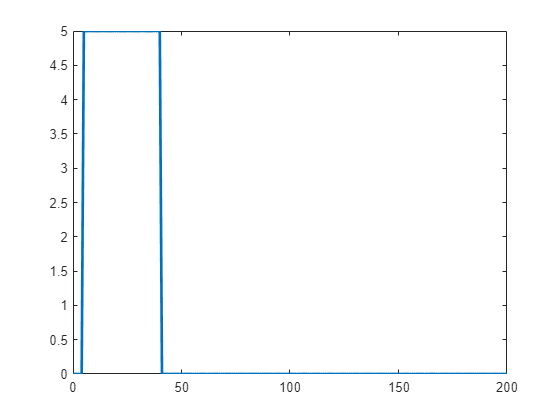

% Input Time Vector
tp = 0:200;

t1 = 5;     % Pulse Start Time
t2 = 40;    % Pulse End Time

% Input Values
p = zeros(size(tp));    % Initialized as a vector of 0
p(tp>=t1 & tp<=t2)=5;   % Set the values within the time interval

plot(tp,p,'Linewidth',2)

We then obtain the output response using `lsim`.

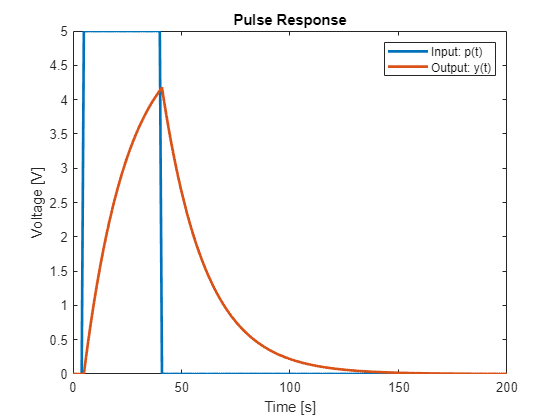

[y,ty] = lsim(G,p,tp);
plot(tp,p,ty,y,'LineWidth',2)
title('Pulse Response')
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Input: p(t)','Output: y(t)')

We can also study how well our output tracks the input based on the value of the resistance `R`. Notably, as `R` increases, our circuit becomes significantly slower and less able to track its input. 

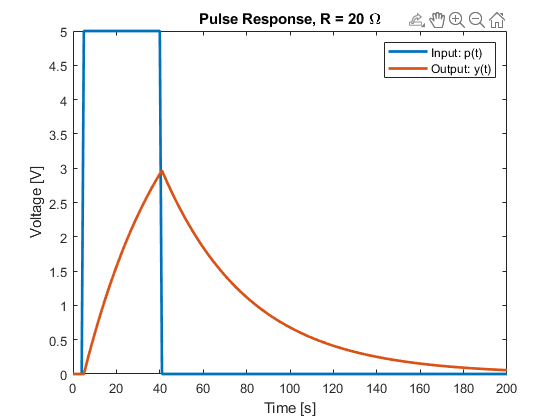

for Rval = .2:.2:20
    % Define Transfer Function
    Gr  = 1/(1+Rval*C*s);
    
    % Compute pulse response
    [y,ty] = lsim(Gr,p,tp);
    
    % Plot the Response
    plot(tp,p,ty,y,'LineWidth',2)
    title(['Pulse Response, R = ' num2str(Rval) ' \Omega'])
    xlabel('Time [s]')
    ylabel('Voltage [V]')
    legend('Input: p(t)','Output: y(t)')
    pause(0.1)
end

#### Response to a Sinusoid

To study how the system reacts to the sinusoid


$$x\left(t\right)=\cos \left(\omega \;t\right)\ldotp$$


As before, we define our input in terms of a time vector `tx` and the corresponding values of `x` and then compute our output using `lsim`.

% Input Time Vector
tx = 0:0.1:500;

% Input Values
w = .05;
x = cos(w*tx); 

We then obtain the output response using `lsim`.

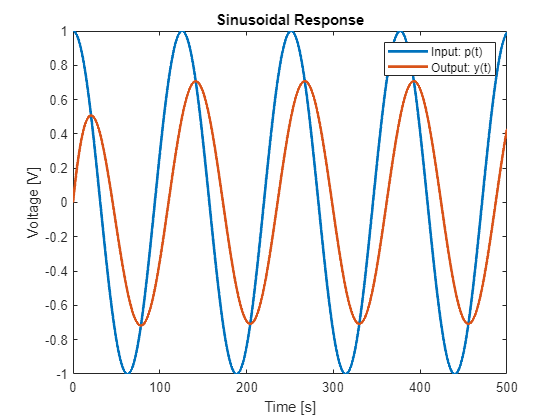

[y,ty] = lsim(G,x,tx);
plot(tx,x,ty,y,'LineWidth',2)
title('Sinusoidal Response')
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Input: p(t)','Output: y(t)')

Note that the output features a little transient at the beginning (more or less the first $50\;s$), but eventually converges to a sinusoid with a constant amplitude and constant frequency.

We can study how well our output tracks the input based on the value of the resistance `R`. For our specifi circuit, we once again note that higher values of `R` lead to worse tracking capabilities. 

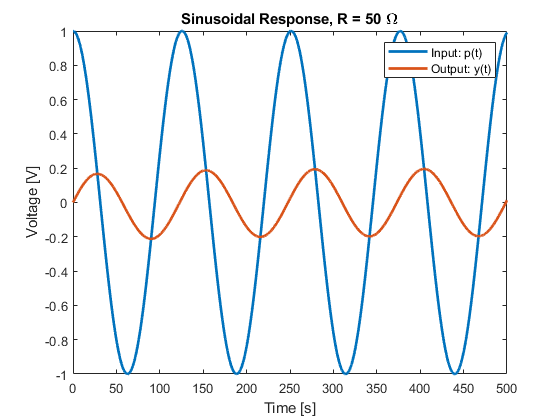

for Rval = .5:.5:50
    % Define Transfer Function
    Gr  = 1/(1+Rval*C*s);
    
    % Compute pulse response
    [y,ty] = lsim(Gr,x,tx);
    
    % Plot the Response
    plot(tx,x,ty,y,'LineWidth',2)
    
xlim("auto")
ylim("auto")
    title(['Sinusoidal Response, R = ' num2str(Rval) ' \Omega'])
    xlabel('Time [s]')
    ylabel('Voltage [V]')
    legend('Input: p(t)','Output: y(t)')
    pause(0.1)
end

# Test your skills

### High-Pass Configuration

Study the behavior of the transfer function


$$G\left(s\right)=\frac{\mathrm{RC}\;s}{1+\mathrm{RC}\;s},$$


obtained by measuring the voltage of an RC circuit across the resistor instead of the capacitor.